## IMAGE PROCESSING

### Color channels

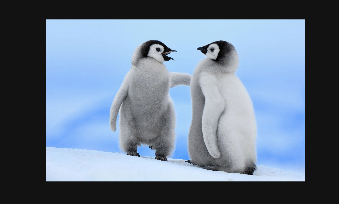

I0 = imread("images/pengu.jpg");
imshow(I0)

size(I0)

ans =         1800        2880           3


max(max(I0))

ans = 1×1×3 uint8 array
ans(:,:,1) =

   242


ans(:,:,2) =

   248


ans(:,:,3) =

   255


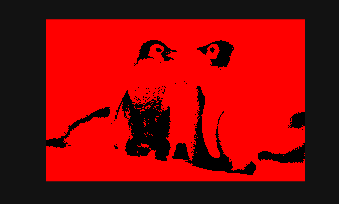

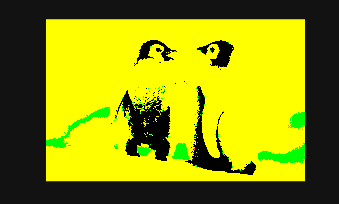

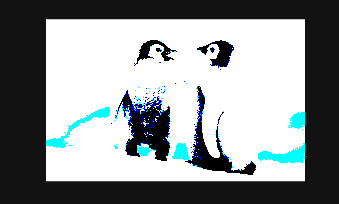

I = I0/255;
I_col = zeros(size(I));

for i = 1:3
    I_col(:, :, i) = I(:, :, i);
    figure
    imshow(I_col);
end


figure

### Image Conversion

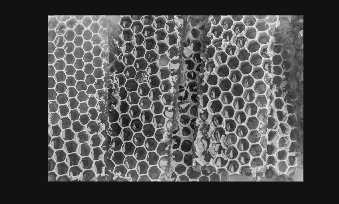


I1 = imread("images/honey-comb.jpg");
imshow(rgb2gray(I1))

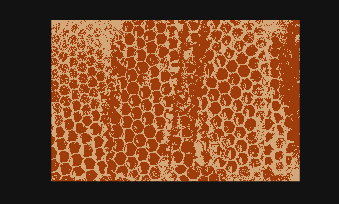

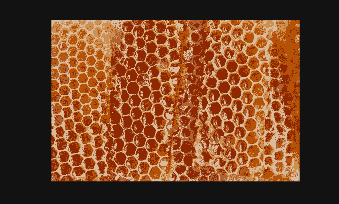

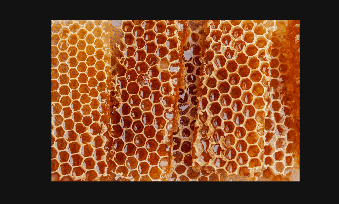

for i = [2 5 50]
    [X, map] = rgb2ind(I1, i);
    figure; imshow(X, map)
end

### Sampling

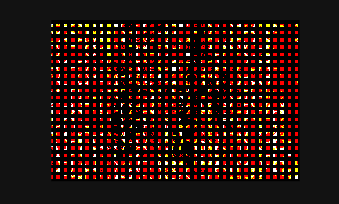

[r, c, s] = size(I1);
N = 2;
I1s = I1/255;
y = zeros(size(I1s));
y(1:N:r, 1:N:c, :) = I1s(1:N:r, 1:N:c, :);
imshow(y)

### Noisy Image

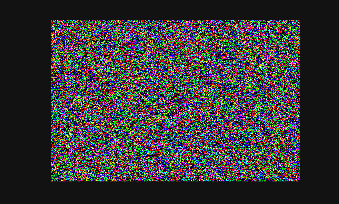

imshow(imnoise(I1s, "gaussian", 0, 1));

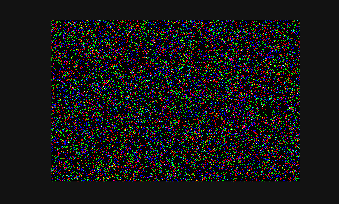

imshow(imnoise(I1s, "salt & pepper", 0.19));

### Bit Resolution

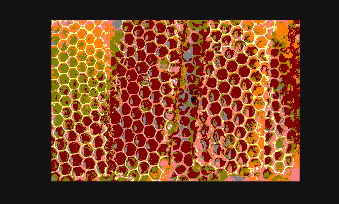

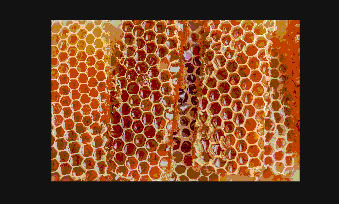

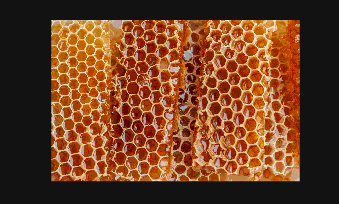


b = [7 6 5];
for i = 1 : length(b)
    d = 2^b(i);
    z = round(I1/d);
    figure
    imshow(z*d)
end

### Image Operations

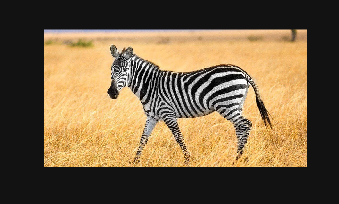

I2 = imread("images/zebra.jpg");
imshow(I2, []);

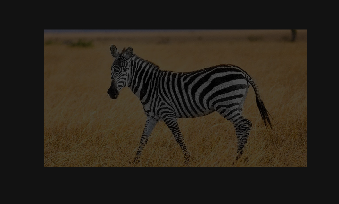


I1c = I1(1:627, 1:1200, :);

imshow(0.3 * I2);

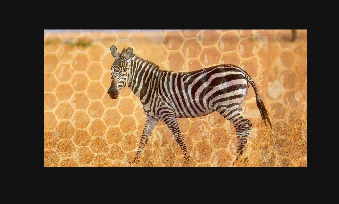


imshow(0.7 * I2 + 0.3 * I1c);

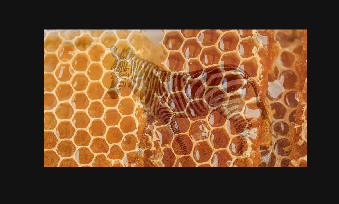

imshow(0.7 * I1c + 0.3 * I2);

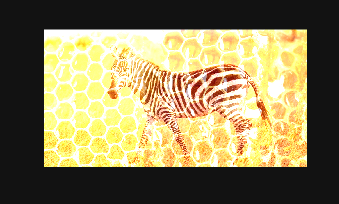


% imadd()
imshow(imadd(I2, I1c));

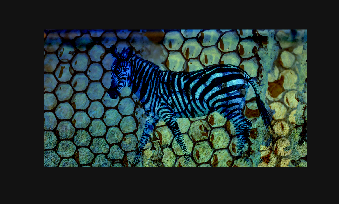

imshow(imsubtract(I2, I1c));

imshow(I2 - I1c);

imshow(I1c - I2);
imshow(imabsdiff(I2, I1c));
%image subtraction is useful for scene change detection
imshow(imdivide(I1c, I2));

### Ex: Double the columns to have mirror image

I2s = im2double(I2);
[r, c, s] = size(I2s);
res = zeros(r, c*2, s);
I2m = flip(I2s, 2);
res(:,1:2:size(res, 2)-1,:) = I2s(:,:,:);
res(:,2:2:size(res, 2),:) = I2m(:,:,:);
imshow(res);
